clear;

Download the dataset comprising images of handwritten digits in http://yann.lecun.com/exdb/ mnist; this has been downloaded in the folder “data” and stored as “mnist.mat”. As of now, for each digit, each 28 × 28 pixel image is represented using 282 coordinate values in the Euclidean space of dimension 282 . 

Suppose you decide to re-represent the images using only 84 coordinates (instead of 282 = 784) in a 84-dimensional basis for some 84-dimensional hyperplane within the original Euclidean space, such that the chosen 84-dimensional hyperplane maximizes the total dispersion of the original data (for the chosen digit) within the hyperplane. 

%see prev prob
load('mnist.mat');
for i = (0:9)
    ddata = digits_train(:,:,labels_train==i);
    dig{i+1} = double(reshape(ddata,28*28,[]));
end

covs = []; % all covs kept together
for i = (1:10)
    [sx,sy] = size(dig{i});
    dmean = sum(dig{i},2)/sy;
    dcov = dig{i}*(dig{i}')/(sy-1) - sy*dmean*dmean'/(sy-1);
    covs = cat(3,covs,dcov);
end

• (5 points) Write a function to compute those 84 coordinates, for each of the ten digits (0–9). 

coordinates=zeros(784,84,10);%784*84*10 matrix
for i =(1:10)
    [Q,D] = eig(covs(:,:,i));
    eigens = sort(diag(D));
    eigens = eigens(701:784);
    %return concatenated relevant coordinate vectors
    W = ismember(D,eigens);
    W(:,~any(W,1))=[];
    V = Q*W;
    coordinates(:,:,i) = V;
end

• (5 points) Give an algorithm for regenerating / reconstructing the image using those 84 coordinates (and the knowledge of the designed 84-dimensional basis). For each of the ten digits (0–9), pick an image, and show the original and the reconstructed images side by side.

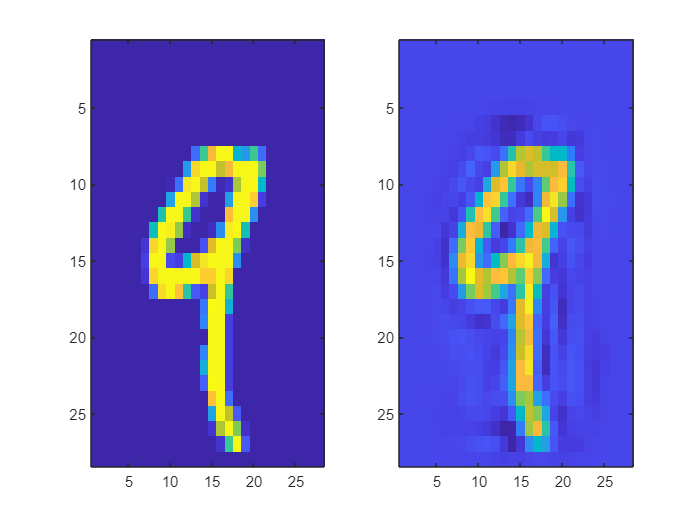

for i = (1:10)
    img = dig{i}(:,1);
    %bb believe me when i say im reducing the dimensions
    recim = coordinates(:,:,i)*coordinates(:,:,i)'*img;
    subplot(1,2,1);%old
    imagesc(reshape(img,28,28))
    subplot(1,2,2);%new
    imagesc(reshape(recim,28,28))
end